close all; clear all; clc;

w = logspace(-2,1,1e3); % frequency range from 10^-2 to 10^1
G = tf(1,[1 0 0])

G =
 
   1
  ---
  s^2
 
Continuous-time transfer function.
Model Properties


% Get Bode plot data
[mag,phase] = bode(G,w);
mag = 20*log10(mag);
% Gain margin, phase margin, gain crossover, phase crossover
[GM,PM,wgc,wpc] = margin(G)

GM = 1

PM = 0

wgc = 1

wpc = 1

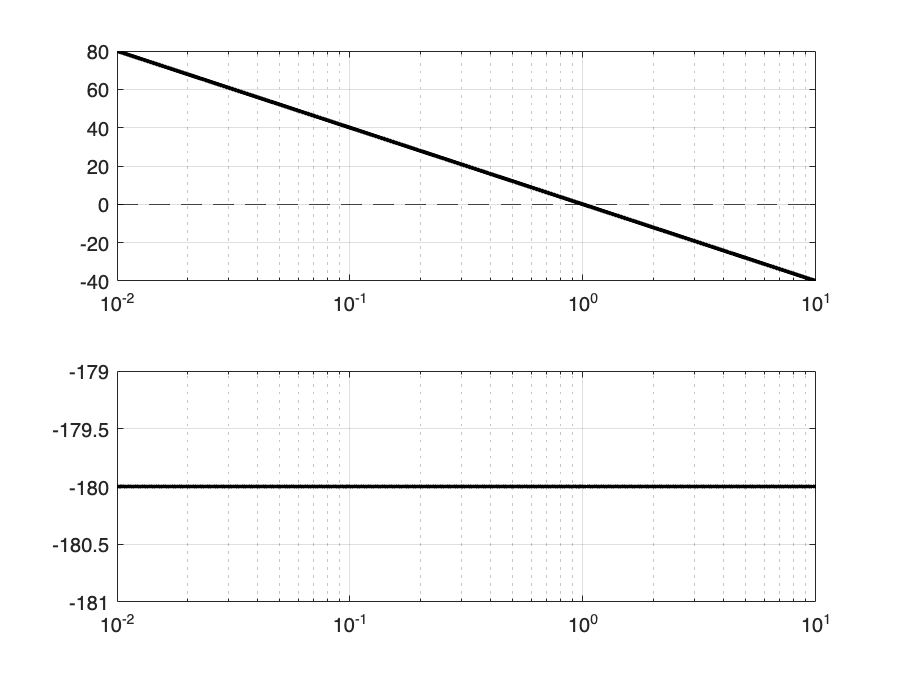


figure(1)
subplot(211)
semilogx(w,squeeze(mag),'k','LineWidth',2)
grid on, hold on
yline(0,'k--'), hold on
subplot(212)
semilogx(w,squeeze(phase),'k','LineWidth',2)
grid on, hold on

% Transfer function with PD compensator
Gcomp = tf(1,[1 0 0])*tf([25 1],1)

Gcomp =
 
  25 s + 1
  --------
    s^2
 
Continuous-time transfer function.
Model Properties



% Get new forward path Bode plot data
[magc,phasec] = bode(Gcomp,w);
magc = 20*log10(magc);
[GMc,PMc,wgcc,wpcc] = margin(Gcomp)

GMc = 0

PMc = 89.9083

wgcc = 0

wpcc = 25.0000

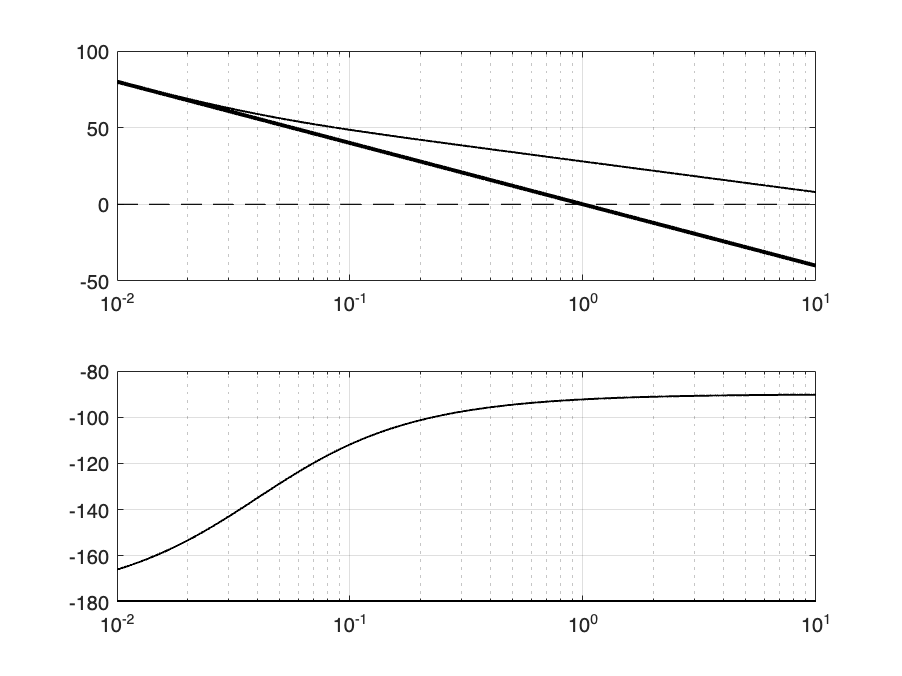

�figure(1)
subplot(211)
semilogx(w,squeeze(magc),'k','LineWidth',1)
grid on, hold on
semilogx(w,0*w./w,'k--'), hold on
subplot(212)
semilogx(w,squeeze(phasec),'k','LineWidth',1)
grid on, hold on

Gfinal = 1/127.5*tf(1,[1 0 0])*tf([25 1],1)

Gfinal =
 
  0.1961 s + 0.007843
  -------------------
          s^2
 
Continuous-time transfer function.
Model Properties


�
[magf,phasef] = bode(Gfinal,w);
magf = 20*log10(magf);
[GMf,PMf,wgcf,wpcf] = margin(Gfinal)

GMf = 0

PMf = 78.6880

wgcf = 0

wpcf = 0.2000

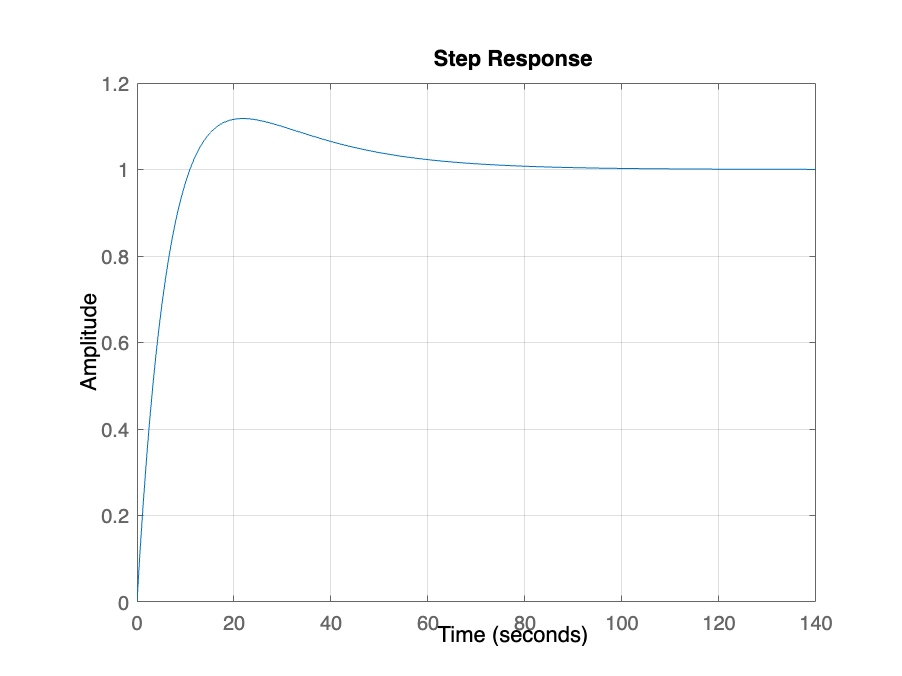


T = Gfinal/(1+Gfinal);
�figure;
step(T), grid on

stepinfo(T)

ans = struct with fields:
         RiseTime: 7.8214
    TransientTime: 62.3702
     SettlingTime: 62.3702
      SettlingMin: 0.9095
      SettlingMax: 1.1179
        Overshoot: 11.7850
       Undershoot: 0
             Peak: 1.1179
         PeakTime: 21.6956


% Sensitivity Function
S = minreal(1/(1+Gfinal))

S =
 
             s^2
  -------------------------
  s^2 + 0.1961 s + 0.007843
 
Continuous-time transfer function.
Model Properties


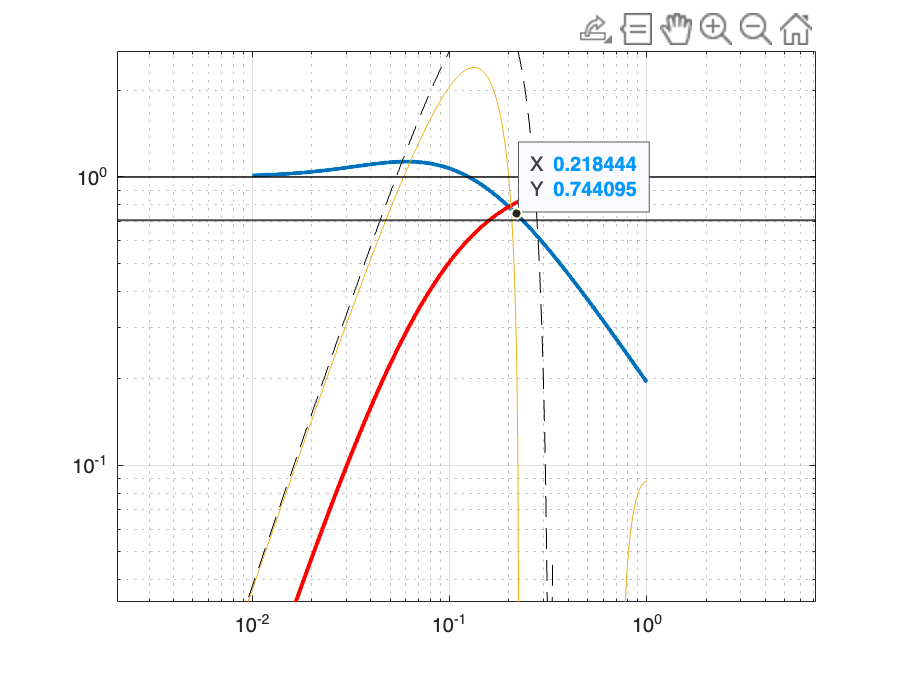

w = logspace(-2,0,1e3); % 10^-2 to 10^2
[magT,phaseT] = bode(T,w); % closed loop frequency response
[magS,phaseS] = bode(S,w); % sensitivity function frequency response
�
figure;
loglog(w,squeeze(magT),'-','LineWidth',2)
grid on, hold on
loglog(w,squeeze(magS),'r-','LineWidth',2), hold on
yline(1,'k-','LineWidth',1)
yline(0.707,'k-','LineWidth',1)
ylim([0.1,1.2])
�%% Disturbance sim
wd = 0.5; % disturbance frequency 
pd = round(2*pi/wd); % disturbance period 
tend = 3*pd; 
h = 0.01;
t = 0:h:tend;
td = 0:h:pd;   
% disturbance time series
d = [2*pi/180*(1-cos(wd*td)),0*[pd+h:h:tend]];
�% Simulation
[y,t] = lsim(S,d,t);
figure(5)
plot(t/tend,y*180/pi,t/tend,d*180/pi,'k--'), grid on